# TPA 2 Grupo 10

## Control con 2DOF-PID

clear all; close all; clc;
s=tf('s');
model_6 = 1/(( (10e3)*(10e-6)*s + 1 )^6)


model_6 =
 
                                   1
  --------------------------------------------------------------------
  1e-06 s^6 + 6e-05 s^5 + 0.0015 s^4 + 0.02 s^3 + 0.15 s^2 + 0.6 s + 1
 
Continuous-time transfer function.
Model Properties



[p, z] = pzmap(model_6);
high_freq_pole = abs(max(p));

% TIEMPO DE MUESTREO
% Ts = round(1/(5*high_freq_pole), 3)

Ts=1e-3

Ts = 1.0000e-03


model_discrete = c2d(model_6, Ts)


model_discrete =
 
  1.377e-15 z^5 + 7.782e-14 z^4 + 4.088e-13 z^3 + 4.053e-13 z^2 + 7.585e-14 z + 1.319e-15
  ---------------------------------------------------------------------------------------
           z^6 - 5.94 z^5 + 14.7 z^4 - 19.41 z^3 + 14.41 z^2 - 5.707 z + 0.9418
 
Sample time: 0.001 seconds
Discrete-time transfer function.


[model_A, model_B, model_C, model_D] = tf2ss(model_discrete.Numerator{1}, model_discrete.Denominator{1});

Se carga el modelo de orden 1 y se muestra en comparación al de orden 6 'medido'

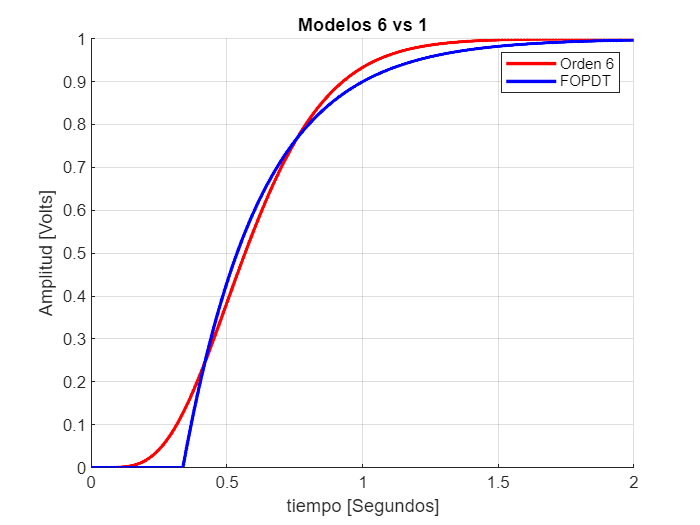

L = 0.33791;
T = 0.28802;
fopdt = 1/(s*T+1);
fopdt.inputDelay = L;

time_vector = 0:1e-3:2;
[y1] = step(model_6, time_vector);
[y2] = step(fopdt, time_vector);

figure; hold on; grid on;
plot(time_vector, y1, 'r', 'LineWidth', 2);
plot(time_vector, y2, 'b', 'LineWidth', 2);

title('Modelos 6 vs 1');
ylabel('Amplitud [Volts]');
xlabel('tiempo [Segundos]');
legend('Orden 6', 'FOPDT');


fprintf('EMC del FOPDT: %.3f\n', immse(y1, y2));

EMC del FOPDT: 0.001



[p, z] = pzmap(fopdt)

p = -3.4720


z =

  0×1 empty double column vector




T_poles = 1/p

T_poles = -0.2880

La idea es tener un controlador con filtro como el siguiente: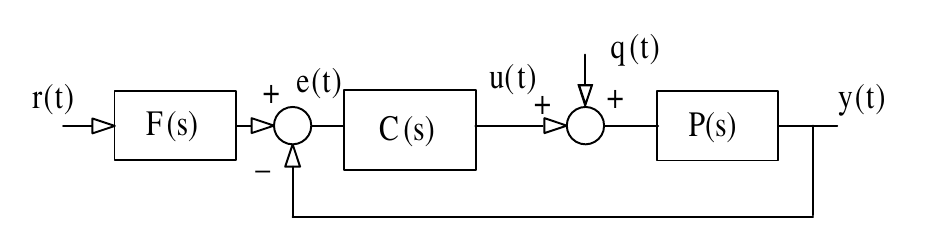

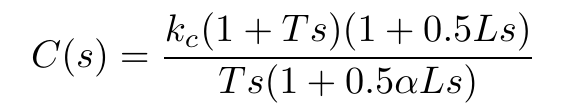

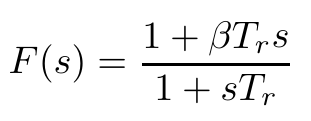

El ajuste de los valores del controlador y el filtro se hacen en base al modelo FOPDT de la planta, y luego quedan como parámetros de ajuste de robustez y performance $\alpha \;y\;\beta$

  se elige para eliminar el efecto del cero dominante

T0=0.5;
beta=0.8;

Kc=T/(L+T0);
alpha=1/(1+L/T0);
C=Kc*(1+T*s)*(1+0.5*L*s)/(T*s*(1+0.5*alpha*L*s))


C =
 
  0.01673 s^2 + 0.1571 s + 0.3437
  -------------------------------
       0.02904 s^2 + 0.288 s
 
Continuous-time transfer function.
Model Properties


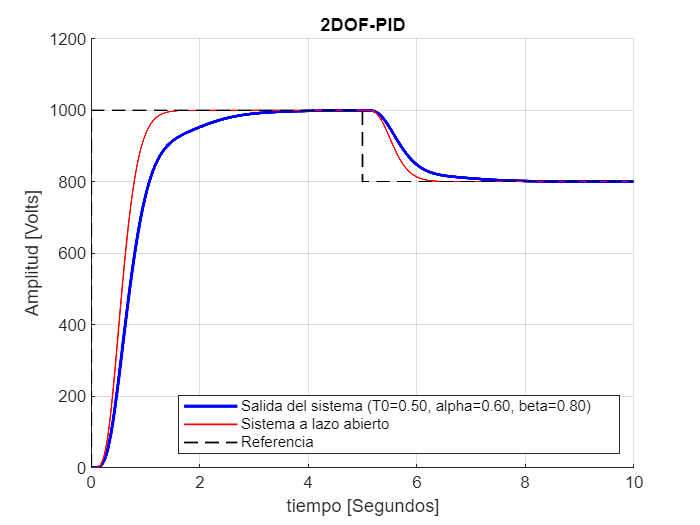

% F=(1+beta*L*0.5*s)/(1+s*L*0.5)
F=1;j

time_vector = 0:1e-3:10;
ref=1000;
reference = ref*ones(1, length(time_vector)); reference(1)=0;

closed_loop_system = F*C*model_6/(1+C*model_6);
perturbance=zeros(1, length(time_vector));perturbance(round(length(perturbance)*0.5):end)=0.2*ref;
reference=reference-perturbance;
[y] = lsim(closed_loop_system, reference, time_vector);
[y_ol] = lsim(model_6, reference, time_vector);

figure; hold on; grid on;
ylim([0 ref*1.2]);
plot(time_vector, y, 'b', 'LineWidth', 2);
plot(time_vector, y_ol, 'r', 'LineWidth', 1);
plot(time_vector, reference, '--k', 'LineWidth', 1);

title('2DOF-PID');
ylabel('Amplitud [Volts]');
xlabel('tiempo [Segundos]');
legend(sprintf('Salida del sistema (T0=%.2f, alpha=%.2f, beta=%.2f)', T0, alpha, beta), 'Sistema a lazo abierto', 'Referencia', 'Location', 'southeast');

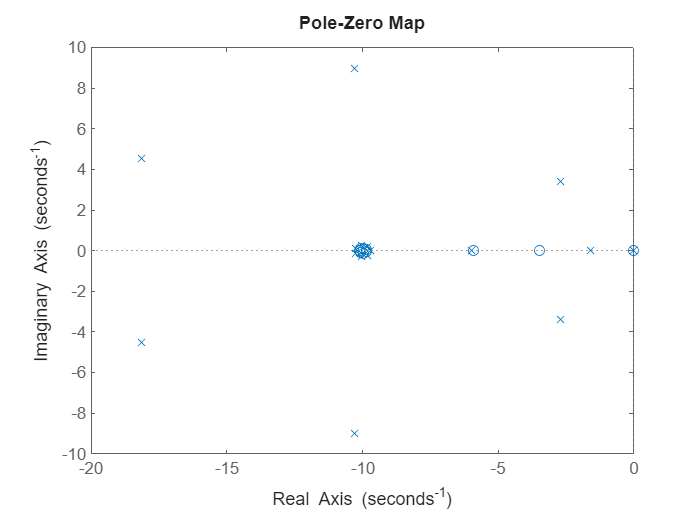


figure()
pzmap(closed_loop_system)

Discretización del controlador

% Ts = T/10;
Ts=1e-3

Ts = 1.0000e-03

PID_discrete = c2d(C, Ts, 'zoh')


PID_discrete =
 
  0.576 z^2 - 1.147 z + 0.5707
  ----------------------------
     z^2 - 1.99 z + 0.9901
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


[num, den] = tfdata(PID_discrete, 'v')

num =     0.5760   -1.1467    0.5707


den =     1.0000   -1.9901    0.9901


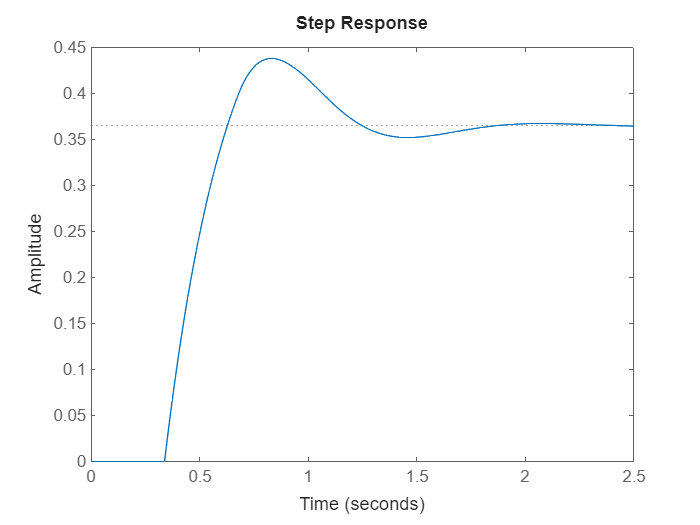


figure();
controller_discrete = tf(num, den);
step(controller_discrete *fopdt/(1+controller_discrete *fopdt))


b0 =  den(3)

b0 = 0.9901


% num = num/den(3);
% den = den/den(3);

u_gains = zeros(1, length(den)-1);
e_gains = zeros(1, length(num));

for i = 1:length(num)
    e_gains(4-i) = num(i)/den(3);
end

for i = 2:length(den)
    u_gains(4-i) = den(i-1)/den(3);
end

e_gains

e_gains =     0.5764   -1.1581    0.5818


u_gains

u_gains =    -2.0100    1.0100


Datos para el código en C

filename='codigo/include/PID.h';
fid = fopen(filename, 'w');
if fid == -1
    error('Error opening the file: %s', filename);
end

guard = upper(strrep('PID.h', '.', '_'));
fprintf(fid, '#ifndef %s\n#define %s\n\n', guard, guard);

fprintf(fid, "const float gains_e[%d] = {", length(e_gains));
for i = 1:(length(e_gains)-1)
    fprintf(fid, " %f,", e_gains(i));
end
fprintf(fid, " %f};\n\n", e_gains(end));

fprintf(fid, "const float gains_u[%d] = {", length(u_gains));
for i = 1:(length(u_gains)-1)
    fprintf(fid, " %f,", u_gains(i));
end
fprintf(fid, " %f};\n\n", u_gains(end));

fprintf(fid, '#endif // %s\n', guard);

fclose(fid);

Hago una simulación de lo que implementaría en C para ver que las ganancias y la realimentación esté bien

time_vector = 0:0.02:10;

states = zeros(length(model_A), 1);
reference = ones(1, length(time_vector));
y = zeros(1, length(time_vector));
u = zeros(1, length(time_vector));

e_gains

e_gains =     0.5764   -1.1581    0.5818


u_gains

u_gains =    -2.0100    1.0100



for i = 3:(length(time_vector)-1)

    e0 = reference(i) - y(i);
    e1 = reference(i-1) - y(i-1);
    e2 = reference(i-2) - y(i-2);
    u2 = u(i-2);
    u1 = u(i-1);

    u(i) = e_gains(3)*e2 + e_gains(2)*e1 + e_gains(1)*e0 - u_gains(2)*u2 - u_gains(1)*u1;

    if (u(i) > 5)
        u(i) = 5;
    elseif (u(i) < 0)
        u(i) = 0;
    end

    % states = model_A*states + model_B*u(i);
    % y(i+1) = model_C*states;

    [y_, ~, ~] = lsim(model_6, u(1:i), time_vector(1:i));
    y(i) = y_(end);

end

y

y =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0011    0.0013    0.0015    0.0017    0.0019    0.0023    0.0026    0.0030    0.0035    0.0041    0.0047    0.0055    0.0064


u

u =          0         0    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0006    0.0007    0.0008    0.0010    0.0011    0.0013    0.0015    0.0017    0.0020    0.0023    0.0026    0.0029    0.0033    0.0038    0.0043    0.0050    0.0057    0.0066    0.0076    0.0088    0.0102    0.0119    0.0139    0.0163    0.0191    0.0223    0.0262    0.0307    0.0359    0.0421    0.0492    0.0576    0.0673    0.0787    0.0918    0.1071    0.1249    0.1455    0.1695    0.1974


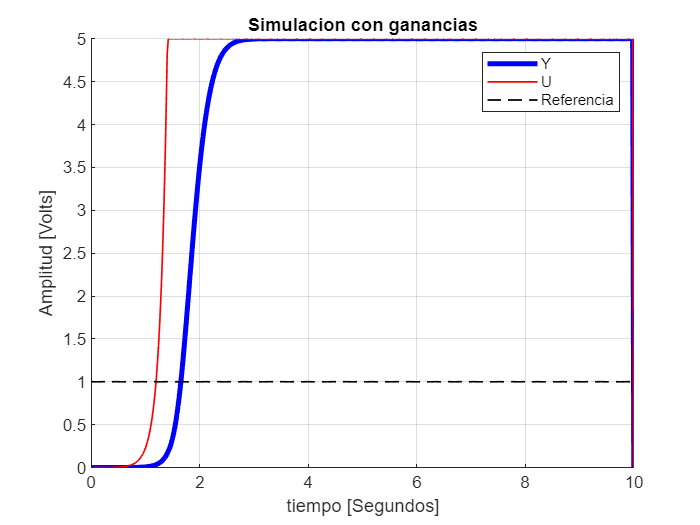


figure; hold on; grid on;
plot(time_vector, y, 'b', 'LineWidth', 3);
plot(time_vector, u, 'r', 'LineWidth', 1);
plot(time_vector, reference, '--k', 'LineWidth', 1);

title('Simulacion con ganancias');
ylabel('Amplitud [Volts]');
xlabel('tiempo [Segundos]');
legend('Y', 'U', 'Referencia');